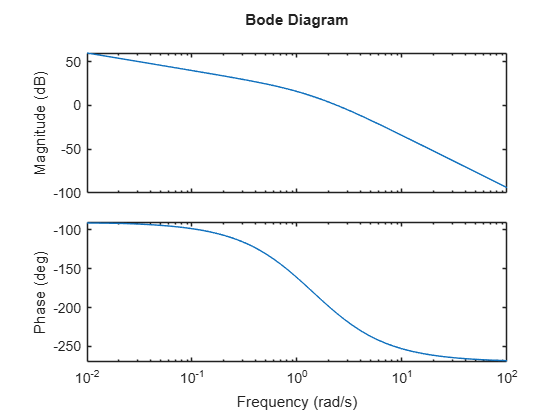

% erro de velocidade = 1/kv
% kv = lim s*K*1/(s*(s+1)*(s+2)) = 0.5*K
% para um erro de velocidade <= 10
% 10 = 1/(0.5*K)
% K = 20

% Margem de fase de ao menos 50°
% Margem de ganho de, no minimo, 10db
MF = 50;

s = tf('s');
K = 20;
G = 1/(s*(s+1)*(s+2));
Gl = K*G;
bode(Gl)


% Avanço de fase
% em 0db, wg (frequencia de cruzamento de ganho) = 2.41rad/s e -208°, portanto, margem de fase = -208 -(-180) = -28°

% para fase em -180°, wf = 1.4rad/s e margem de ganho de 10.3 db

a = (1 - sind(MF+8))/(1 + sind(MF+8))

a = 0.0822

b = 1/a

b = 12.1621

WmMag = -20*log10(sqrt(b))

WmMag = -10.8501

Wm = 3.92 % rad/s (nova frequencia de cruzamento de ganho)

Wm = 3.9200


T1 = sqrt(b)/Wm

T1 = 0.8896


% Atraso de fase

% 1/T2 = wf/10

T2 = 10/1.4

T2 = 7.1429


Gc = K*((T1*s+1)/((T1/b)*s+1)*(T2*s+1)/(b*T2*s+1))


Gc =
 
  127.1 s^2 + 160.7 s + 20
  ------------------------
  6.355 s^2 + 86.95 s + 1
 
Continuous-time transfer function.


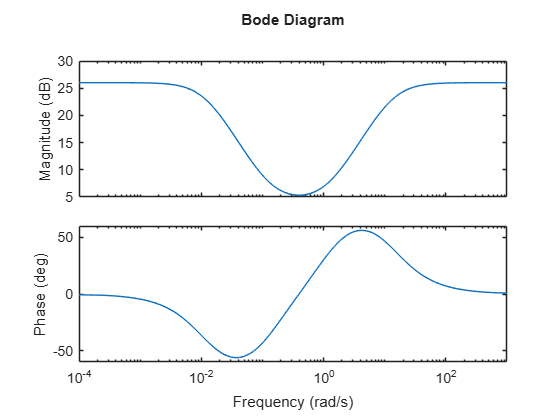

bode(Gc)


step(feedback(G,1))
hold
step(feedback(Gc*G,1),'--red')